# Лабораторная работа №2

Геометрические преобразования изображений

clc
clear all

I = imread('spb.jpg');

**Сдвиг изображения**

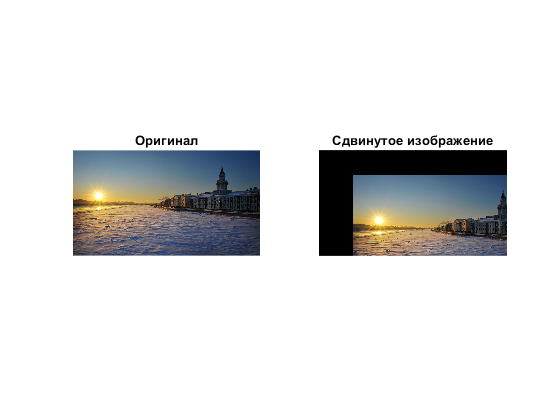

C = 350;
D = 250;
T = [1 0 0; 0 1 0; C D 1]; % задаём матрицу преобразований
tform = affine2d(T); % создаём матрицу преобразований
I_shift = imwarp(I, tform, 'OutputView',imref2d(size(I),...
    [1 size(I,2)], [1 size(I,1)])); % применяем матрицу к изображению

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_shift)
title('Сдвинутое изображение')

**Отражение изображения**

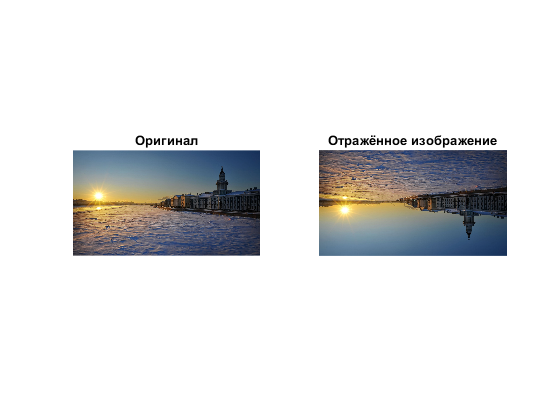

T = [1 0 0; 0 -1 0; 0 0 1];
tform = affine2d(T);
I_reflect = imwarp(I,tform);

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_reflect)
title('Отражённое изображение')

**Однородное масштабирование изображения**

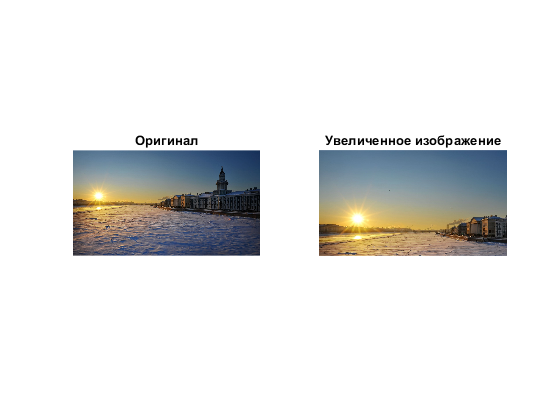

alpha = 1.5;
betta = 1.5;

T = [alpha 0 0; 0 betta 0; 0 0 1];
tform = affine2d(T);
I_scale = imwarp(I, tform, 'OutputView',imref2d(size(I),...
    [1 size(I,2)], [1 size(I,1)]));

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_scale)
title('Увеличенное изображение')

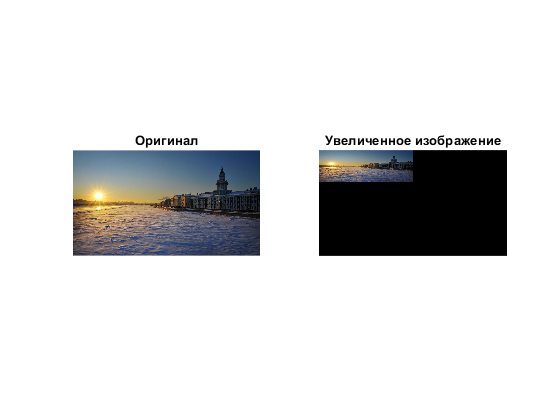

alpha = 0.5;
betta = 0.3;

T = [alpha 0 0; 0 betta 0; 0 0 1];
tform = affine2d(T);
I_scale = imwarp(I, tform, 'OutputView',imref2d(size(I),...
    [1 size(I,2)], [1 size(I,1)]));

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_scale)
title('Увеличенное изображение')

**Поворот**

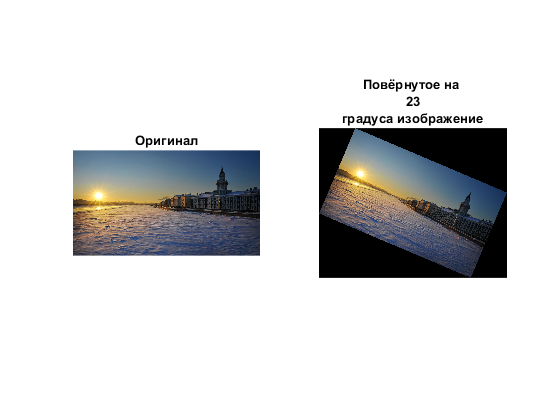

phi = 23 * pi / 180;
T = [cos(phi) sin(phi) 0; -sin(phi) cos(phi) 0; 0 0 1];
tform = affine2d(T);
I_rot = imwarp(I, tform);

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_rot)
title({'Повёрнутое на ', num2str(rad2deg(phi)), 'градуса изображение'})

**Скос изображения**

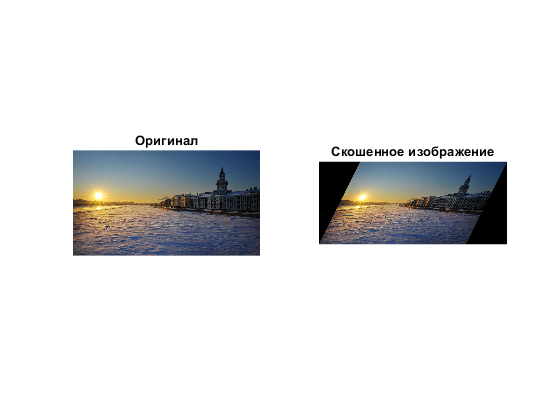

s = -0.5;

T = [1 0 0; s 1 0; 0 0 1];
tform = affine2d(T);
I_skos = imwarp(I,tform);

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_skos)
title('Скошенное изображение')

**Кусочно-линейное отображение**

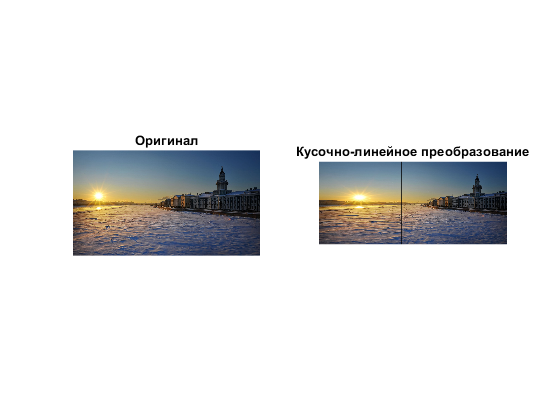

middle = round(size(I,1) / 2);
I_left = I(:,1:middle, :);
strech = 2;
I_right = I(:,(middle + 1:end), :);
T = [strech 0 0; 0 1 0; 0 0 1];
tform = affine2d(T);
I_scale = imwarp(I_left, tform);
I_piecelinear = [I_scale I_right];

figure
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_piecelinear)
title('Кусочно-линейное преобразование')

**Проекционное отображение**

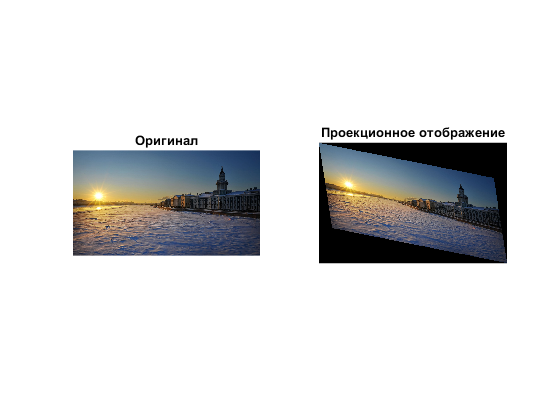

A = 1.5;
B = 0.3;
C = 0;
F = 0;
D = 0.2;
E = 1.3;
G = 0.005;
H = 0.001;
I_k = 4;
T = [A B C; D E F; G H I_k];
tform = projective2d(T);
I_skos = imwarp(I,tform);

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_skos)
title('Проекционное отображение')

**Полиноминальное отображение**

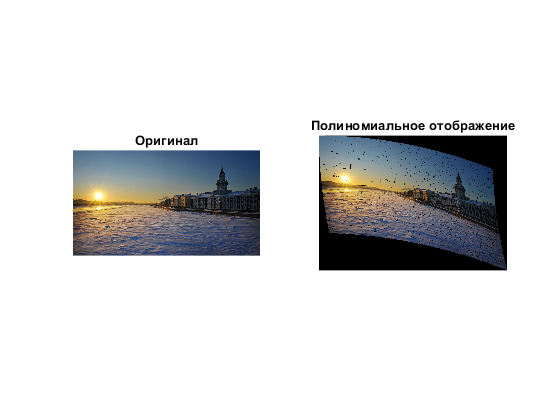

[nRows, nCols, Layers] = size(I);
T = [0 0; 1 0; 0 1; 0 0.0001; 0.00002 0.00002; 0.0001 0];
for k=1:1:Layers
    for y = 1:1:nCols
        for x = 1:1:nRows
            xnew = round(T(1,1) + T(2,1)*x + T(3,1)*y + T(4,1)*x^2+ ...
                T(5,1)*x*y + T(6,1)*y^2);
            ynew = round(T(1,2) + T(2,2)*x + T(3,2)*y + T(4,2)*x^2+ ...
                T(5,2)*x*y + T(6,2)*y^2);
            I_pol(xnew,ynew,k) = I(x,y,k);
        end
    end
end

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_pol)
title('Полиномиальное отображение')

**Синусоидальное искажение**

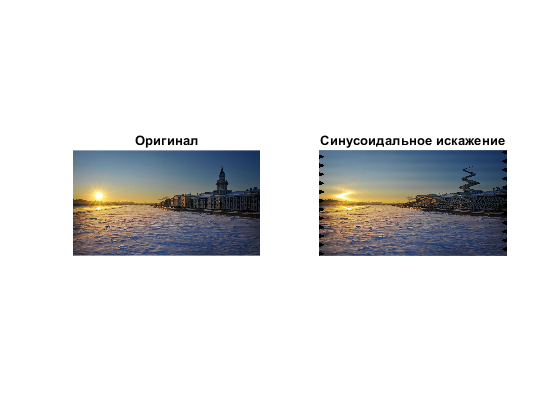

[xi, yi] = meshgrid(1:nCols, 1:nRows);
middle = round(size(I,2) / 2);
u = xi + 50 * sin(2 * pi * yi / 90);
v = yi;
tmap = cat(3,u,v);
resamp = makeresampler('linear','fill');
I_sin = tformarray(I,[],resamp, [2 1], [1 2], [], tmap, 0.3);

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_sin)
title('Синусоидальное искажение')

**Бочкообразная дисторсия**

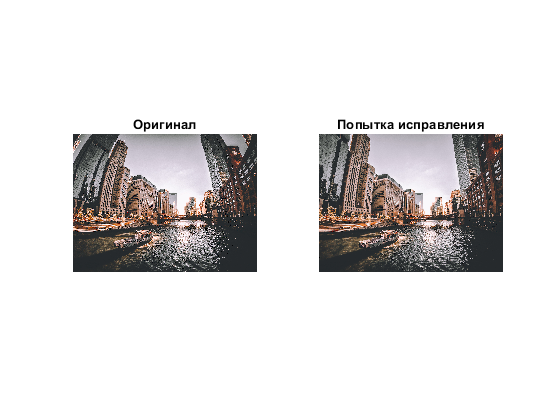

I = imread("city.jpg");

[nRows, nCols, Layers] = size(I);
[xi, yi] = meshgrid(1:nCols, 1:nRows);
middle = round(size(I,2)/ 2);
xt = xi(:) - middle;
yt = yi(:) - middle;

[theta, r] = cart2pol(xt,yt); % для удобства расчёта переводим в полярную СК
F3 = -0.0000000004;
F5 = -0.00000000008;
R = r + F3 * r.^2 + F5 * r.^4;
[ut, vt] = pol2cart(theta,R); % перевод обратно
u = reshape(ut, size(xi)) + middle;
v = reshape(vt, size(yi)) + middle;
tmap_B = cat(3, u, v);
resamp = makeresampler('linear', 'fill');
I_bar = tformarray(I, [], resamp,[2 1], [1 2], [], tmap_B, 0.3);

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_bar)
title('Попытка исправления')

**Подушкообразная дисторсия**

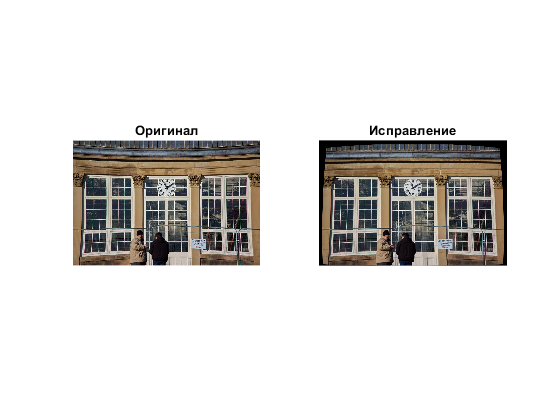

I = imread("pin.jpg");

[nRows, nCols, Layers] = size(I);
[xi, yi] = meshgrid(1:nCols, 1:nRows);
middle = round(size(I,2)/ 2);
xt = xi(:) - middle;
yt = yi(:) - middle;

[theta, r] = cart2pol(xt,yt); % для удобства расчёта переводим в полярную СК
F3 = 0.000000004;
F5 = 0.0000000004;
R = r + F3 * r.^2 + F5 * r.^4;
[ut, vt] = pol2cart(theta,R); % перевод обратно
u = reshape(ut, size(xi)) + middle;
v = reshape(vt, size(yi)) + middle;
tmap_B = cat(3, u, v);
resamp = makeresampler('linear', 'fill');
I_pin = tformarray(I, [], resamp,[2 1], [1 2], [], tmap_B, 0.3);

figure;
subplot(1,2,1)
imshow(I)
title('Оригинал')
subplot(1,2,2)
imshow(I_pin)
title('Исправление')

**Склеивание изображения**

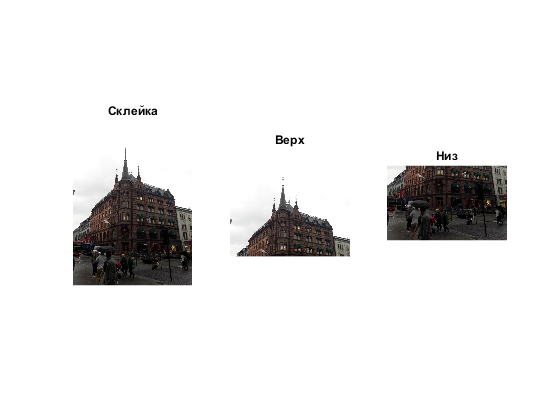

top = imread('top.jpg');
bot = imread('bot.jpg');

topHT = im2double(rgb2gray(top));
botHT = im2double(rgb2gray(bot));


[nRows, nCols, Layers] = size(top);
[nRowsb, nColsb, Layersb] = size(bot);

intersecPart = 10;
botCorrHT = zeros(intersecPart, nCols);
topCorrHT = zeros(intersecPart, nCols);
corArray = [];



for j = 1:1: nCols
    for i = 1:1: intersecPart
        botCorrHT (i, j) = botHT (i, j);
    end
end

for j = 0:1: nRows - intersecPart
    for i = 1:1: intersecPart
        topCorrHT (i ,:) = topHT (i + j,:);
    end
    corCoef =corr2 (topCorrHT , botCorrHT);
    corArray = [corArray corCoef];
    corCoef = 0;
end
[M, I] = max(corArray);

nRowsBotCorr = nRowsb + I - 1;
for k=1:Layers
    for j =1:nCols
        for i= 1:I - 1
            res_img(i,j,k) = top(i,j,k);
        end
        for i = I:1:nRowsBotCorr
            res_img(i,j,k) = bot(i-I+1,j,k);
        end
    end
end
figure;
subplot(1,3,1)
imshow(res_img)
title('Склейка')
subplot(1,3,2)
imshow(top)
title('Верх')
subplot(1,3,3)
imshow(bot)
title('Низ')